Without an input argument, `defaultPlotColors()` will return the array of 7 default plot colors. Each row respresents one color. Row 1 to row 7 correspond to color 1 to 7, respectively.

defaultPlotColors()

ans =          0    0.4470    0.7410
    0.8500    0.3250    0.0980
    0.9290    0.6940    0.1250
    0.4940    0.1840    0.5560
    0.4660    0.6740    0.1880
    0.3010    0.7450    0.9330
    0.6350    0.0780    0.1840


With 'plot' as the input argument, `defaultPlotColors` will plot the 7 default colors in a figure so that you can check their colors visually.

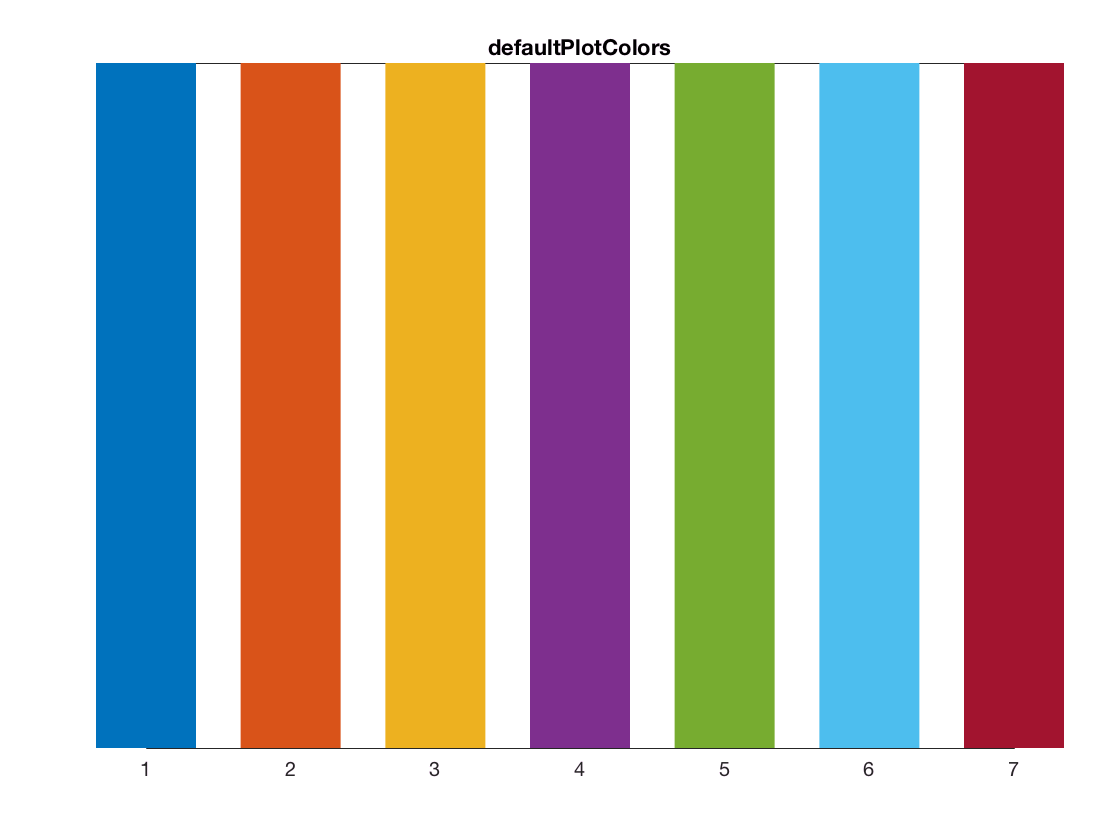

defaultPlotColors('plot')

With a positive integer k as the input argument, `defaultPlotColors` will return the k-th default plot color as `1x3` vector of double.

c = defaultPlotColors(1)

c =          0    0.4470    0.7410


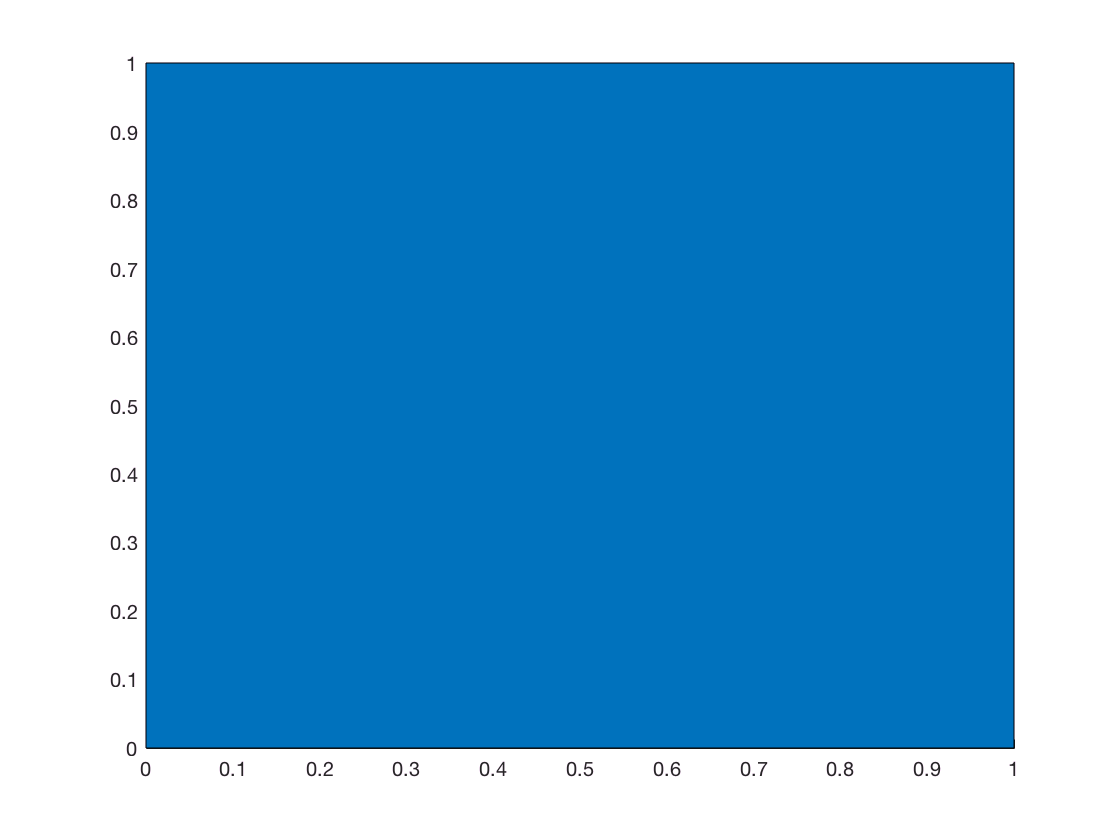

figure
patch([0 0 1 1] ,[0 1 1 0],c)

c = defaultPlotColors(2)

c =     0.8500    0.3250    0.0980



c = defaultPlotColors(7)

c =     0.6350    0.0780    0.1840


When `k` > 7, `defaultPlotColors` will cycle through the 7 default colors and return the specified color.

c = defaultPlotColors(8)

c =          0    0.4470    0.7410


When a vector `A` of positive integers are passed to defaultPlotColors as the input argument, it will return k x 1 array of colors, where n is the length of vector `A`.

A = [1,2,7,9,8,3]

A =      1     2     7     9     8     3


colors = defaultPlotColors(A)

colors =          0    0.4470    0.7410
    0.8500    0.3250    0.0980
    0.6350    0.0780    0.1840
    0.8500    0.3250    0.0980
         0    0.4470    0.7410
    0.9290    0.6940    0.1250


Plot these colors in a figure as below.

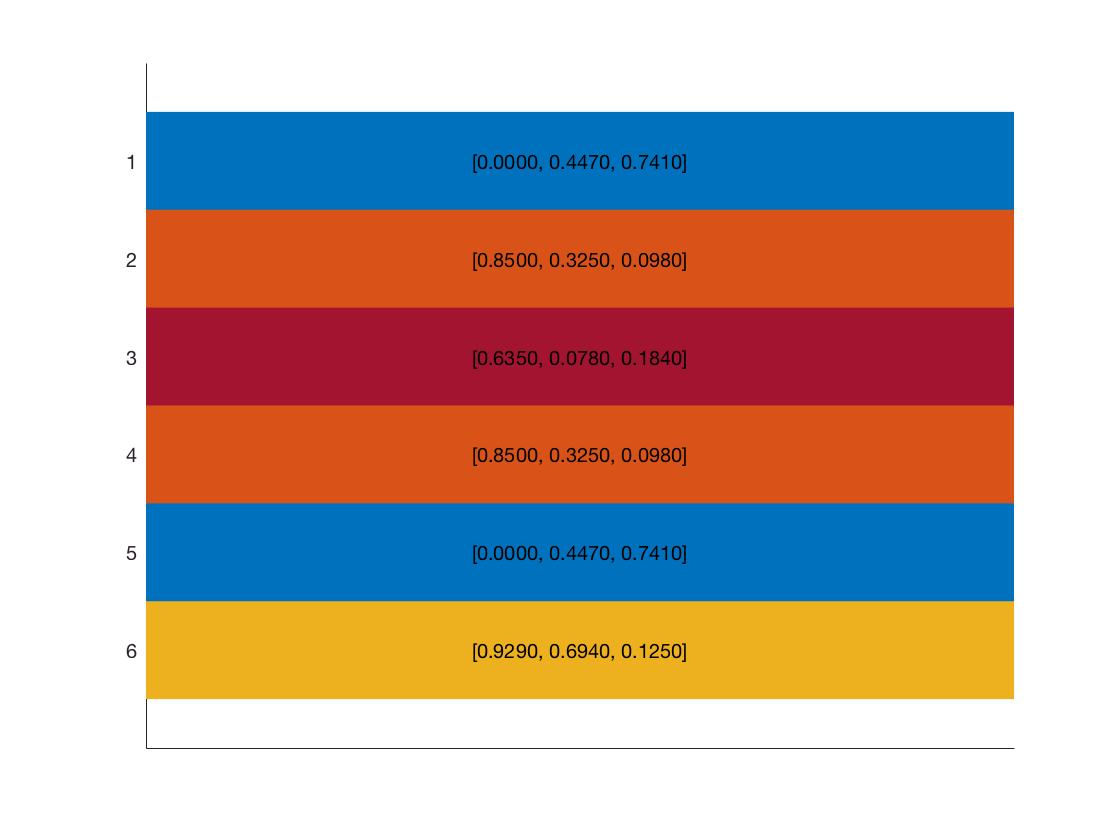

k = size(colors,1);

colors = arrayfun(@(x) colors(x,:), 1:k,'UniformOutput',false);
figure
hold on

n = length(colors);
h = gobjects(n,1);

for i = 1:n
    h(i) = patch([0 0 1 1],[i-1,i,i,i-1]+0.5,colors{i},'EdgeColor','none');
    
    thiscolor = h(i).FaceColor;
    if sum(thiscolor) < 0.6
        txtcolor = 'w';
    else
        txtcolor = 'k';
    end
    text(0.5,i,sprintf('[%.4f, %.4f, %.4f]',...
        thiscolor(1),thiscolor(2),thiscolor(3)),...
        'HorizontalAlignment','center','VerticalAlignment','middle',...
        'Color',txtcolor);
    
end
axh = gca;
axh.YTick = 1:n;
axh.XTick = [];
axh.YDir = 'reverse';